clear all
clc

t = table2array(readtable('Data3.xlsx','Range','A2:A302'));
x = table2array(readtable('Data3.xlsx','Range','B2:B302'));
y = table2array(readtable('Data3.xlsx','Range','C2:C302'));
z = table2array(readtable('Data3.xlsx','Range','D2:D302'));

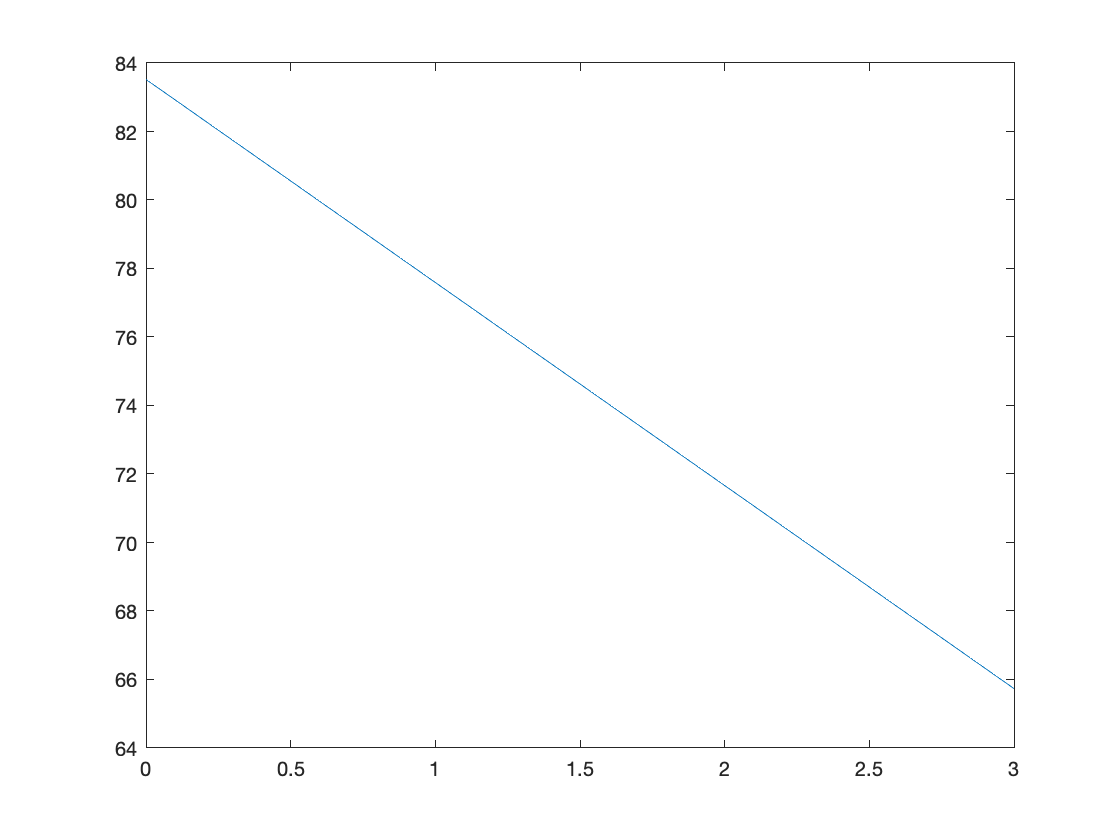

plot(t,x)

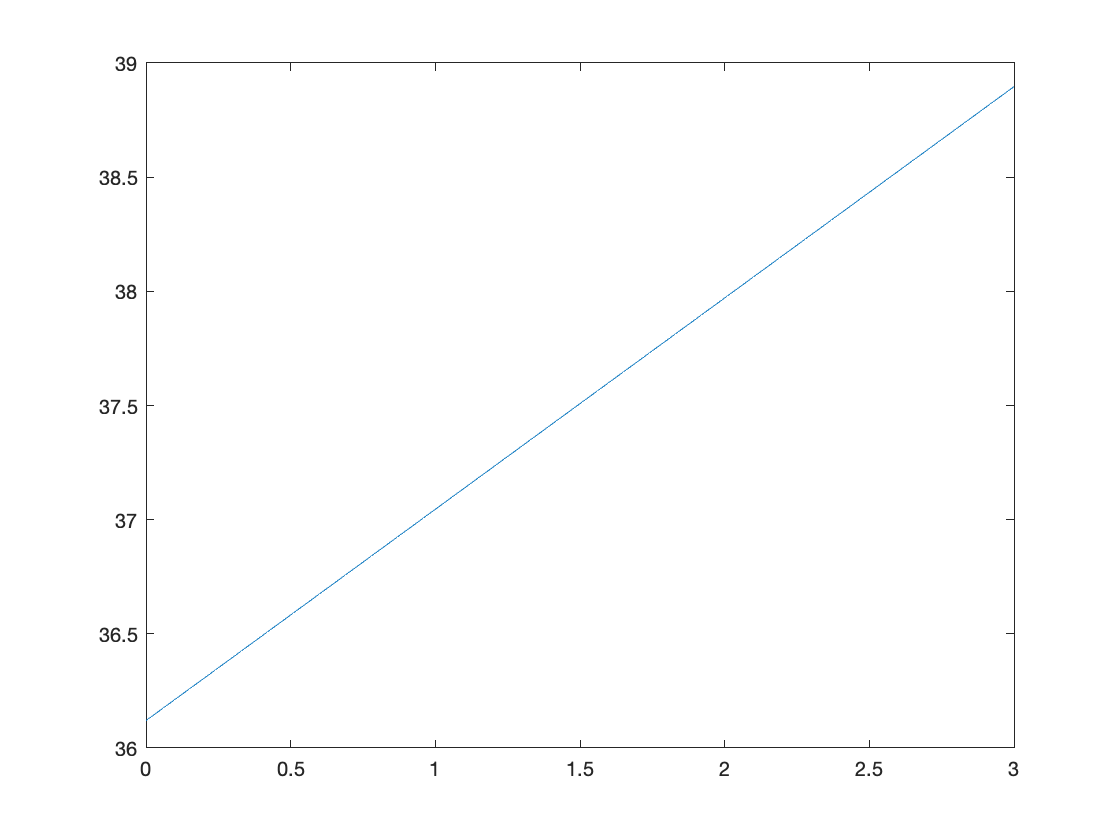

plot(t,y)

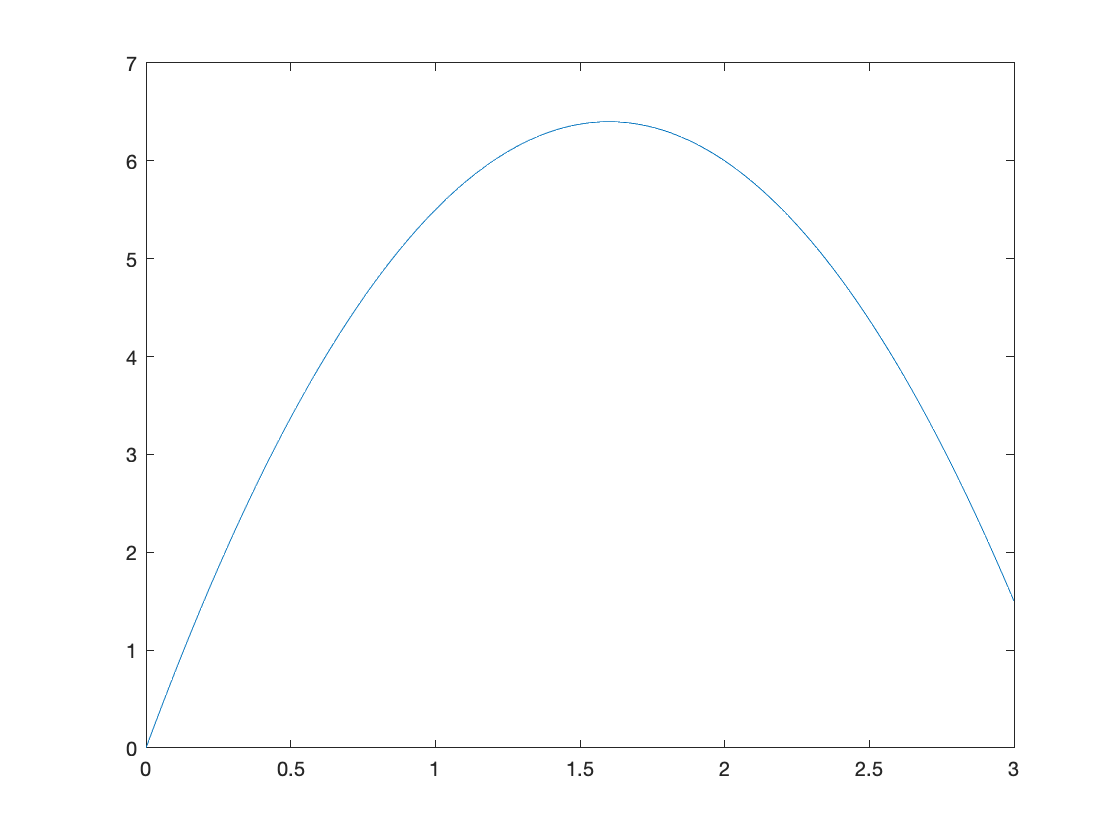

plot(t,z)

fitx = fit(t,x,'poly1')

fitx =      Linear model Poly1:
     fitx(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -5.928  (-5.928, -5.928)
       p2 =       83.52  (83.52, 83.52)

fity = fit(t,y,'poly1')

fity =      Linear model Poly1:
     fity(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9255  (0.9255, 0.9255)
       p2 =       36.12  (36.12, 36.12)

fitz = fit(t,z,'poly2')

fitz =      Linear model Poly2:
     fitz(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =        -2.5  (-2.5, -2.5)
       p2 =           8  (8, 8)
       p3 =    1.22e-15  (8.663e-16, 1.574e-15)

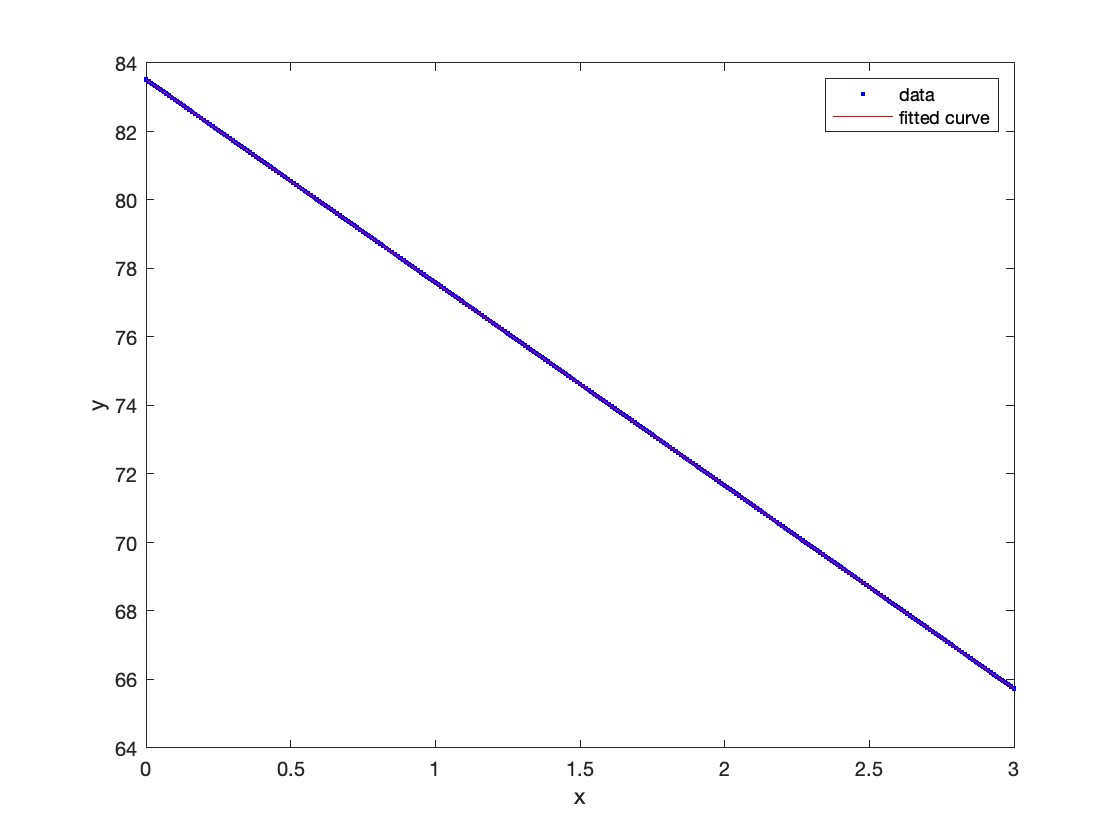

plot(fitx,t,x)

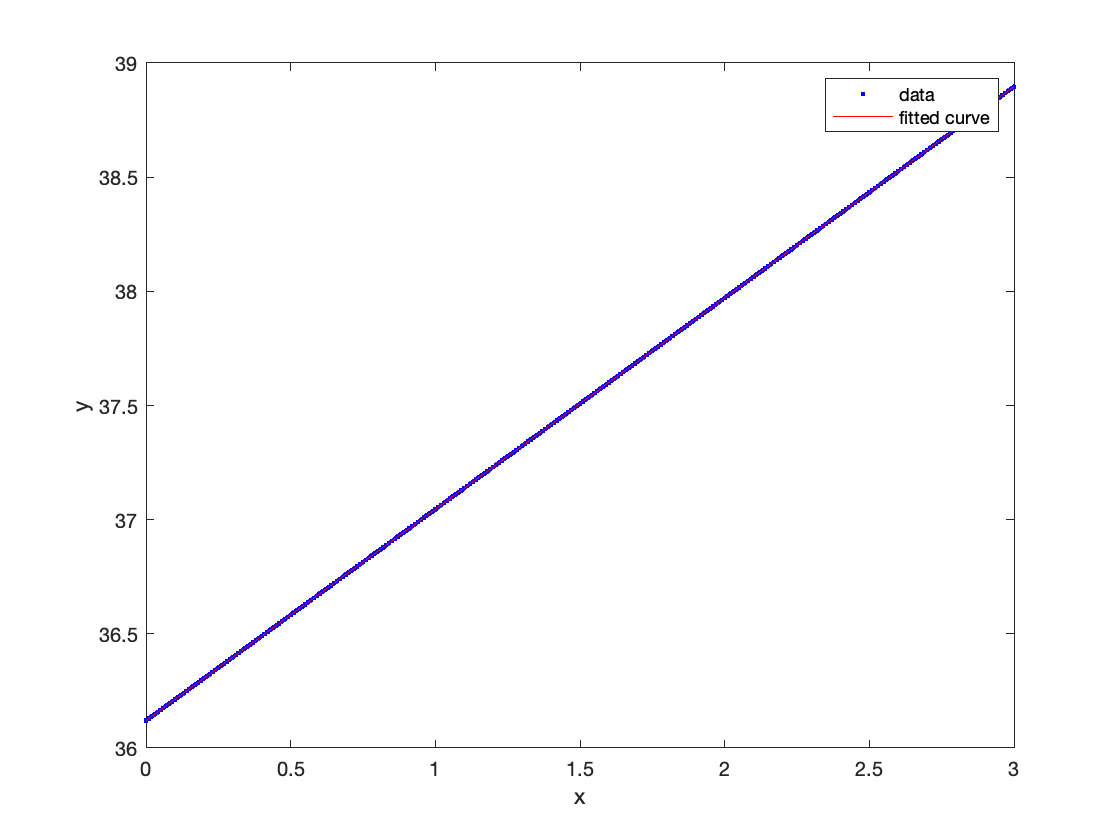

plot(fity,t,y)

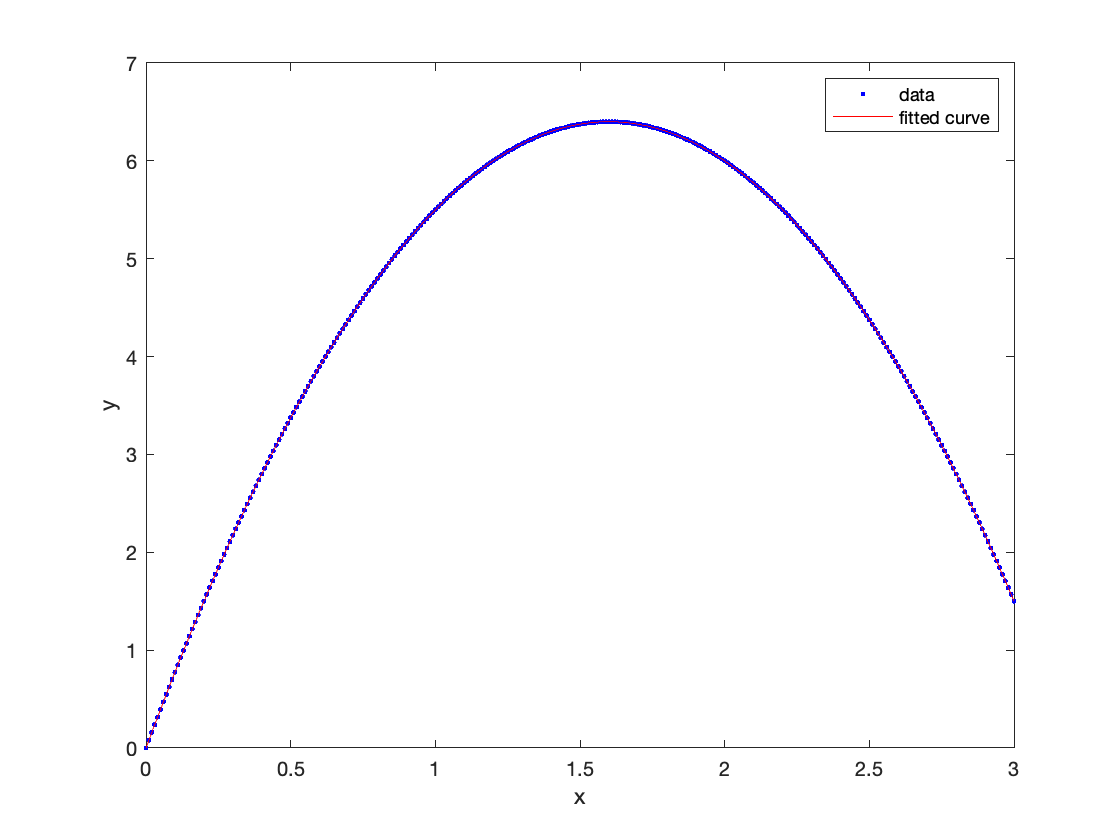

plot(fitz,t,z)